ans = 308.4394

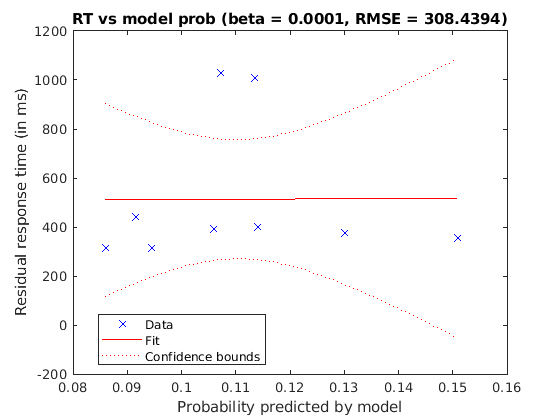

ans = 308.4439

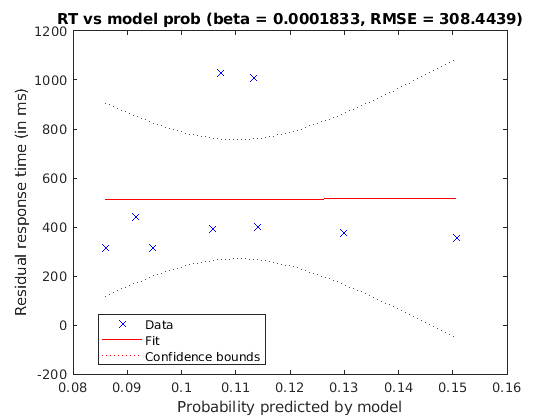

ans = 308.4480

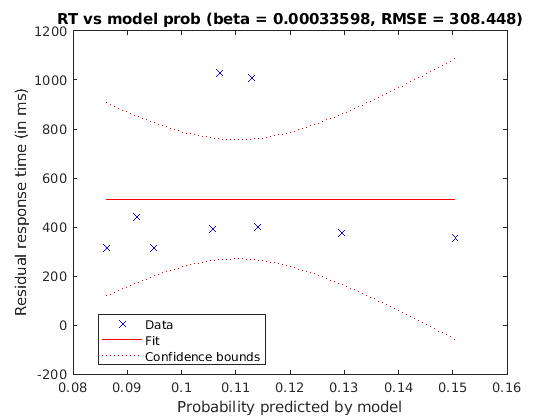

ans = 308.4405

ans = 308.3744

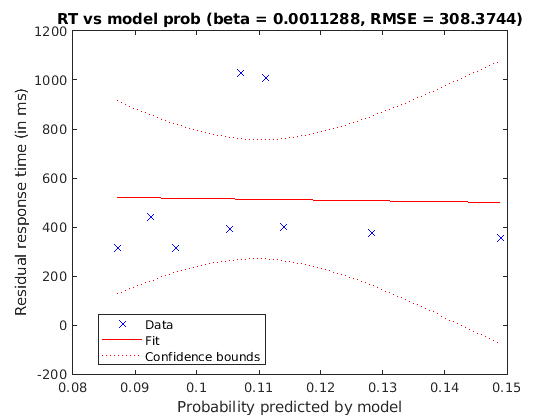

ans = 308.0649

ans = 306.8443

ans = 302.8801

ans = 294.7061

ans = 286.0675

ans = 279.1601

ans = 274.3249

ans = 270.5330

ans = 262.1956

ans = 249.9792

ans = 249.3707

ans = 267.1049

ans = 281.2134

ans = 285.5331

ans = 285.9163

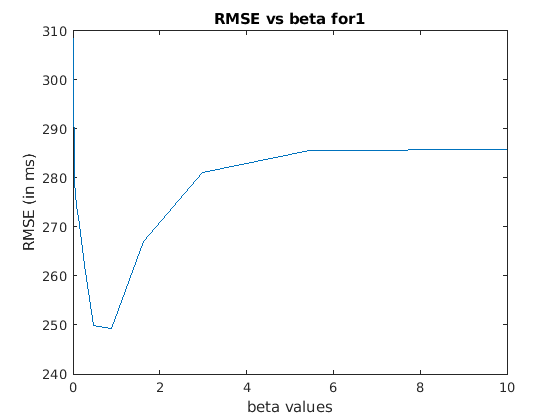

ans = 72.5698

ans = 72.5566

ans = 72.5329

ans = 72.4912

ans = 72.4207

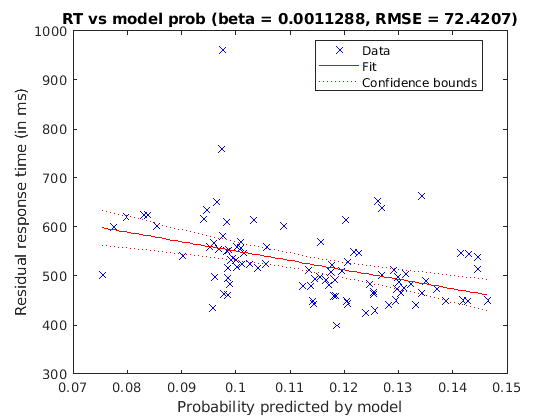

ans = 72.3095

ans = 72.1548

ans = 71.9763

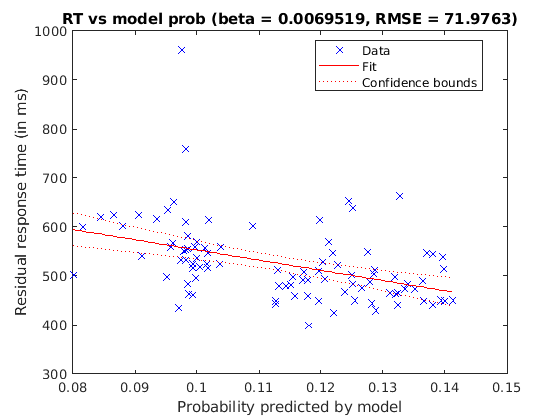

ans = 71.8292

ans = 71.8306

ans = 72.0090

ans = 72.2441

ans = 72.9759

ans = 74.5375

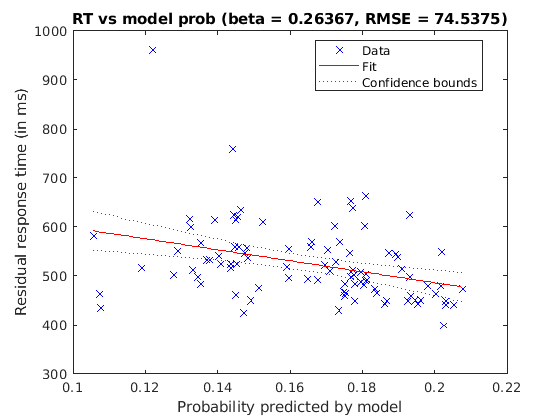

ans = 76.2901

ans = 77.7984

ans = 78.7316

ans = 79.0727

ans = 79.1493

ans = 79.1556

ans = 109.9027

ans = 109.9015

ans = 109.8991

ans = 109.8938

ans = 109.8813

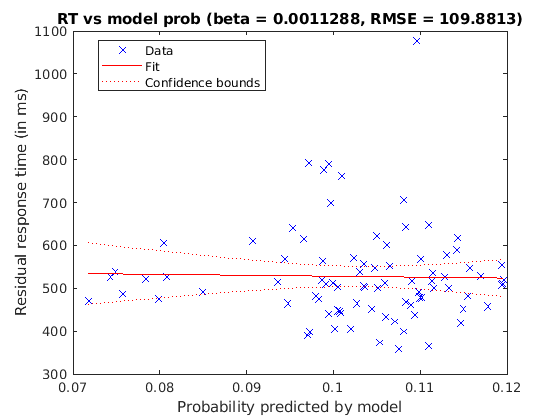

ans = 109.8511

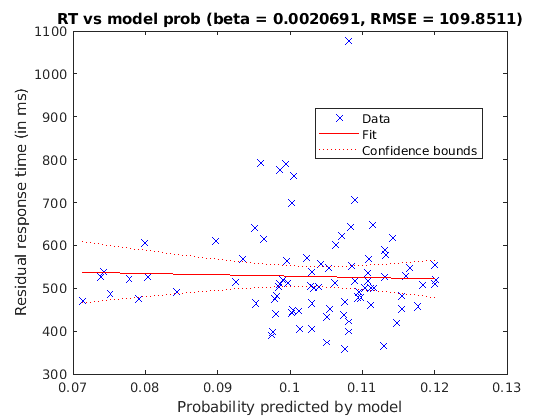

ans = 109.7836

ans = 109.6633

ans = 109.4988

ans = 109.2658

ans = 108.9549

ans = 108.8141

ans = 108.9526

ans = 109.0707

ans = 109.1201

ans = 109.2628

ans = 109.3759

ans = 109.3563

ans = 109.3311

ans = 109.3283

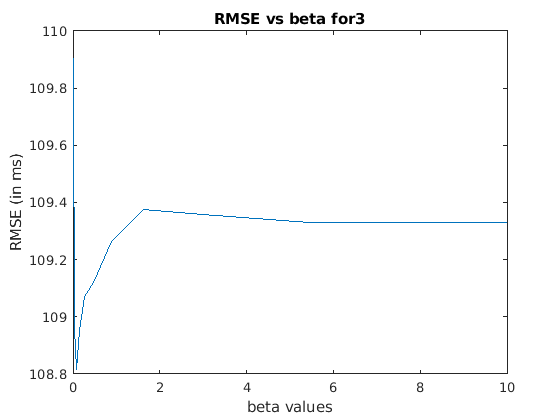

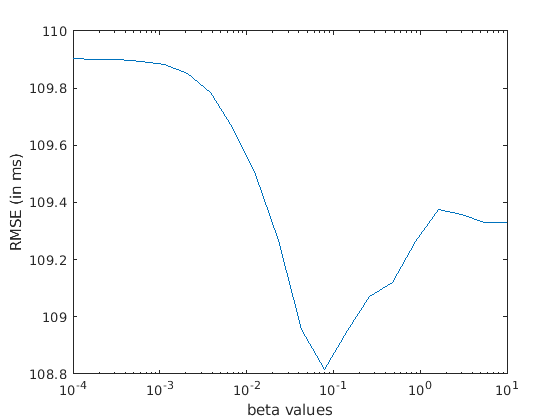

ans = 59.5176

ans = 59.5127

ans = 59.5037

ans = 59.4873

ans = 59.4576

ans = 59.4054

ans = 59.3248

ans = 59.2442

ans = 59.3010

ans = 59.6891

ans = 60.0675

ans = 60.2342

ans = 60.2987

ans = 60.3186

ans = 60.3405

ans = 60.3639

ans = 60.3683

ans = 60.3644

ans = 60.3615

ans = 60.3612

ans = 85.5445

ans = 85.5594

ans = 85.5858

ans = 85.6315

ans = 85.7055

ans = 85.8106

ans = 85.9240

ans = 85.9923

ans = 85.9753

ans = 85.8729

ans = 85.7448

ans = 85.6719

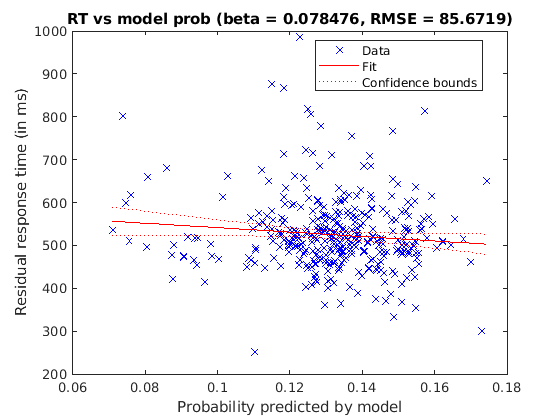

ans = 85.6739

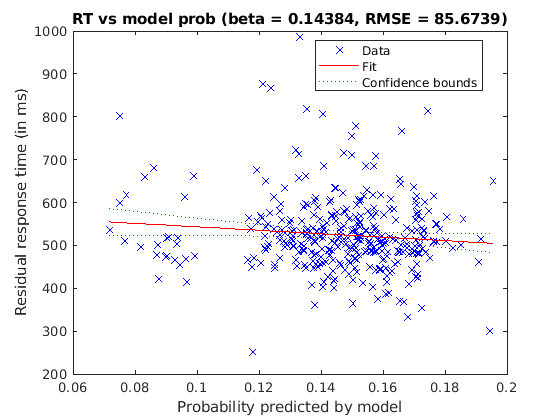

ans = 85.6938

ans = 85.7421

ans = 85.8950

ans = 86.0569

ans = 86.1163

ans = 86.1268

ans = 86.1276

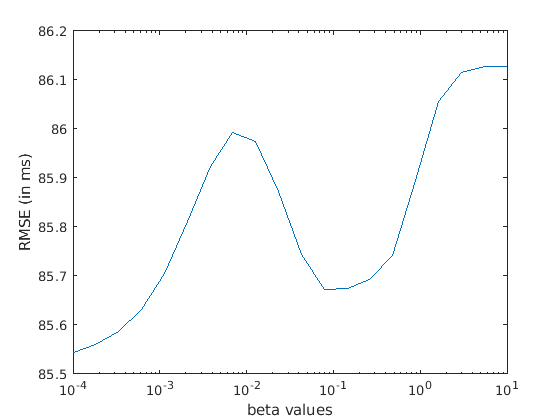

ans = 63.7573

ans = 63.7573

ans = 63.7573

ans = 63.7574

ans = 63.7577

ans = 63.7590

ans = 63.7620

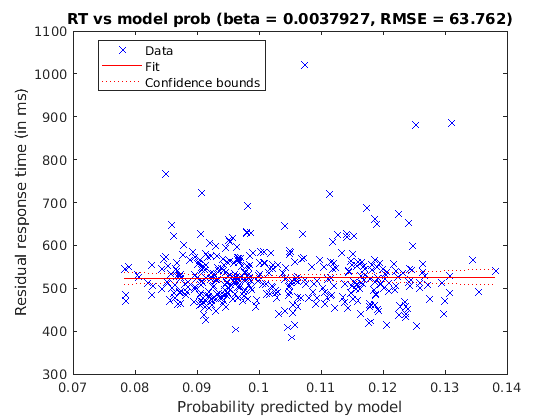

ans = 63.7654

ans = 63.7623

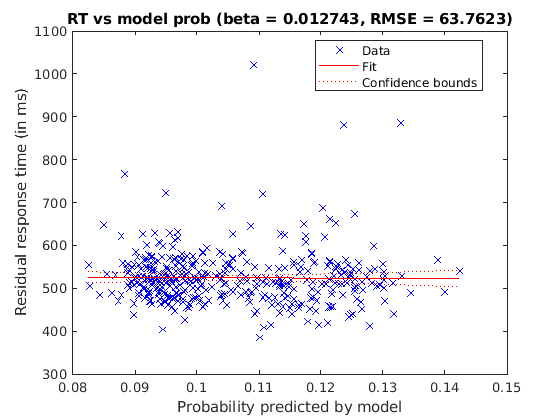

ans = 63.7452

ans = 63.7123

ans = 63.6675

ans = 63.6111

ans = 63.5461

ans = 63.4766

ans = 63.4197

ans = 63.3881

ans = 63.3633

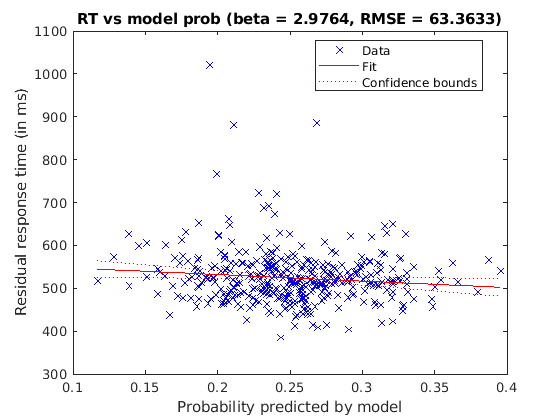

ans = 63.3517

ans = 63.3505

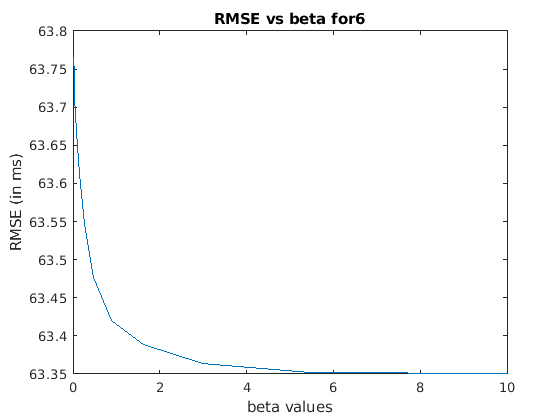

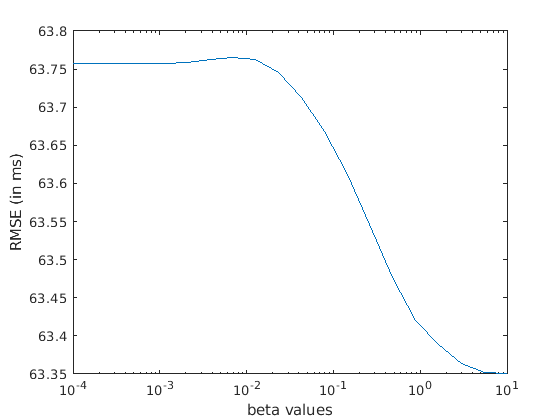

ans = 176.8415

ans = 176.8621

ans = 176.8998

ans = 176.9692

ans = 177.0956

ans = 177.3200

ans = 177.6856

ans = 178.1871

ans = 178.7653

ans = 179.3570

ans = 179.8638

ans = 180.2448

ans = 180.4529

ans = 180.5203

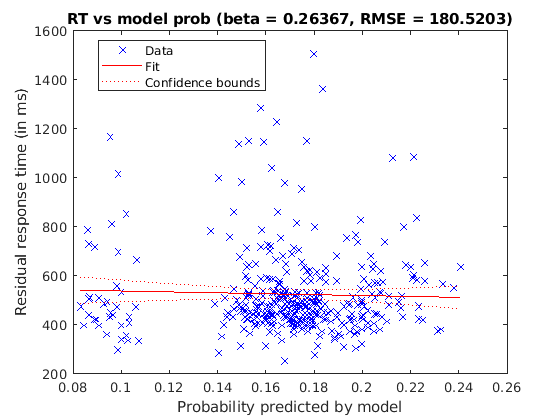

ans = 180.5060

ans = 180.3887

ans = 180.1860

ans = 180.0704

ans = 180.0453

ans = 180.0434

ans = 101.6697

ans = 101.6729

ans = 101.6784

ans = 101.6868

ans = 101.6979

ans = 101.7076

ans = 101.7090

ans = 101.7030

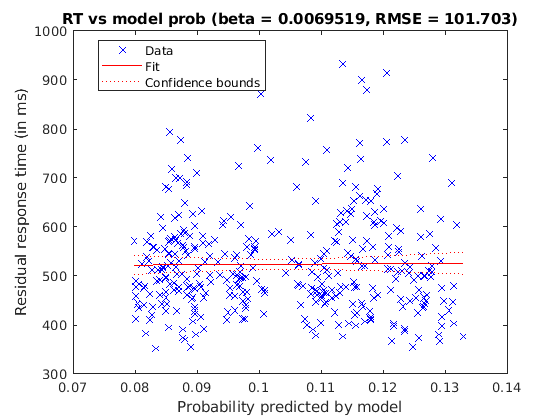

ans = 101.7034

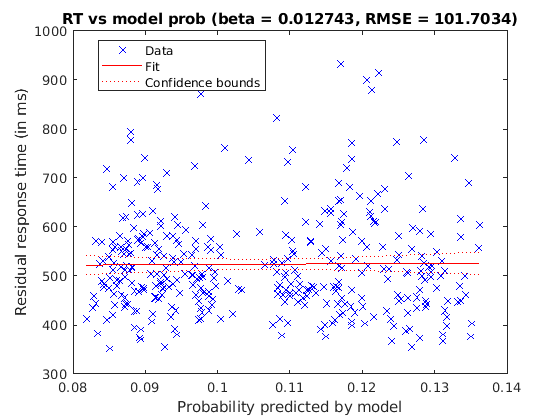

ans = 101.7098

ans = 101.6782

ans = 101.5801

ans = 101.4742

ans = 101.3642

ans = 101.3070

ans = 101.4667

ans = 101.6843

ans = 101.6999

ans = 101.6778

ans = 101.6753

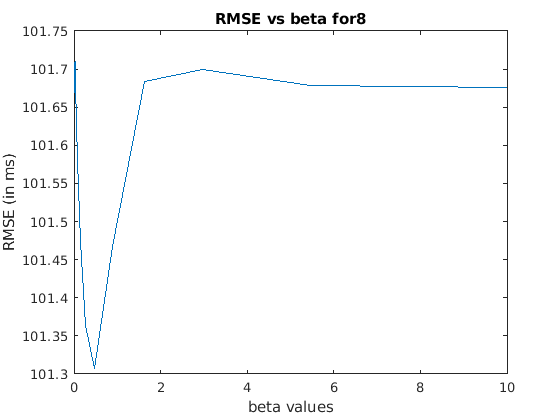

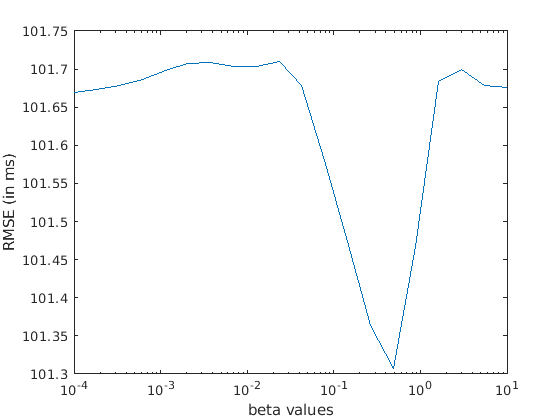

% Analysis of this file:
% Pre-process and filter out reaction times, trials and targets to the
% mixed effects model. 
% Use the unfiltered full target sequence to find model predictions (a)
% Filter out the model predictions and fit a line between these and the
% residuals from the mixed effects model. 
% This file was used after obtaining data from the lab in the end. 
% Author: Akshay Krishnan
% Date last modified: 05-06-2020

% Paths to data CSV files
% target - keys pressed through the sequence
target_file = readmatrix("railH/target-small-graph-h-04.csv");
% trial - the count at which the particular key was pressed
trial_file = readmatrix("railH/trial-small-graph-h-04.csv");
% rt - reaction time file
rt_file = readmatrix("railH/rt-small-graph-h-04.csv");
% graph - adjacency list
graph_file = readmatrix("railH/graph-small-graph-h-04.csv");
% folder to store the plots
plots_folder = 'railH/plots4/';

% initializing variables that are used to store the data read from these
% files
RT = [];
trial = [];
target = [];
ID = []; 
log_trial = [];
mat_size = size(rt_file); % number of subjects
full_target = [];
full_ID = [];
filtered = [];
filtered_ID = [];
mkdir(plots_folder);

for i = 1:mat_size(1)
    % each row of the file is data for one subject.
    % rmmissing removes the NaNs at the end that occur becuase of varying
    % lengths of the sequence for each subject. 
    this_RT = transpose(rmmissing(rt_file(i, :)));
    this_RT_mean = mean(this_RT);
    this_RT_std = std(this_RT);

    % preprocessing data from the reaction times. Filtered according to the
    % paper. Find indices that meet the criteria. 
    filtered_indices = find(this_RT < (this_RT_mean + 3*this_RT_std) & ...
                            this_RT > (this_RT_mean - 3*this_RT_std) & ...
                            this_RT > 100 & this_RT < 3500);
    filtered_indices = filtered_indices(filtered_indices > 600);
    
    RT = [RT; this_RT(filtered_indices)];
    trial = [trial; transpose(1:length(this_RT(filtered_indices)))];
    log_trial = [log_trial; log(transpose(1:length(this_RT(filtered_indices))))];
    this_target = rmmissing(target_file(i, :));
    target = [target; transpose(this_target(filtered_indices))];
    ID = [ID; i*ones(size(this_RT(filtered_indices)))];
    filtered = [filtered; filtered_indices];

    % also store the full unfiltered target sequence for the estimating the model. 
    full_target = [full_target; transpose(this_target)];
    full_ID = [full_ID; i*ones(size(this_RT))];
end

% creating a table - filtered data
pretest_table = table(ID, trial, log_trial, target, RT, filtered);
pretest_table.target = categorical(pretest_table.target);
pretest_table.ID = categorical(pretest_table.ID);

% table - unfiltered full target data
pretest_full_table = table(full_ID, full_target);
pretest_full_table.full_target = categorical(pretest_full_table.full_target);
pretest_full_table.full_ID = categorical(pretest_full_table.full_ID);

% fitting the LME model
model = fitlme(pretest_table, 'RT ~ log_trial + target + (log_trial | ID)');

% residuals of the model + intercept (to avoid negative values of the
% residuals). 
residual_intercept = model.Coefficients.Estimate(1) + residuals(model);
residual_rt = residuals(model);

% range of beta values at which are to be evaluated 
% change this to increase number of beta values
beta_values = logspace(-4, 1, 20);

% list of subjects are to be analysed
subject = 1:mat_size(1);
results = [];

for subj = subject
    % sequence of keys and reaction residuals for this subject
    x = pretest_full_table.full_target(pretest_full_table.full_ID == categorical(subj));
    
    errors = [];   % list of RMSE for different beta
    beta_count = 1;  % counter for iterations - used to save images
    mkdir(plots_folder+string(subj)) % folder for each subject
    
    % for each beta value
    for b = beta_values
        % first determine the model's belief by iterating over the sequence
        belief = zeros([15, length(x)]);
        % the belief of x at each timestep is the sum of prob of all
        % previous time steps where x occured. An alternative way of
        % implementing this is to move from i = 1:t and update the value of
        % x(i) at t. 
        for t = 1:length(x)
            for i = 1:t
                belief(x(i), t) = belief(x(i), t) + prob(t - i, b);
            end
        end
        % a is the transition probability for each transition in the
        % sequence
        a = zeros([length(x), 1]);
        % n in the transition probability matrix at a particular instant
        n = zeros([15, 15]);
        
        % computing the transition probabilities based on the new counting
        % rule
        for t = 1:length(x)-1
            for i = 1:15
                n(i, x(t+1)) = n(i, x(t+1)) + belief(i, t);
            end
            a(t+1) = n(x(t), x(t+1))/sum(n(x(t), :));
        end
        
        a_filtered = a(pretest_table.filtered(pretest_table.ID == categorical(subj)));
        rt_filtered = residual_intercept(pretest_table.ID == categorical(subj));

        linear_model = fitlm(a_filtered, rt_filtered);
        figure;
        plot(linear_model);
        xlabel('Probability predicted by model');
        ylabel('Residual response time (in ms)');
        title('RT vs model prob (beta = '+string(b)+', RMSE = '+string(linear_model.RMSE)+')')
        linear_model.RMSE
        saveas(gcf, plots_folder+string(subj)+'/rt-vs-a-'+string(beta_count)+'.png');
        beta_count = beta_count + 1;
        errors = [errors, linear_model.RMSE];
    end
    % plot and save the RMSE values for different beta
    figure;
    plot(beta_values, errors);
    xlabel('beta values');
    ylabel('RMSE (in ms)');
    title('RMSE vs beta for' + string(subj));
    saveas(gcf, plots_folder+string(subj)+'/rmse-b.png');

    % plot and save the RMSE values for different beta - in log domain for
    % x axis
    figure;
    semilogx(beta_values, errors);
    xlabel('beta values');
    ylabel('RMSE (in ms)');
    saveas(gcf, plots_folder+string(subj)+'/rmse-logb.png');
    close all;
end

function [p] = prob(t, beta)
    p = exp(-beta*t)*(1 - exp(-beta));
end